# 案例：进退法确定搜索最小值区间

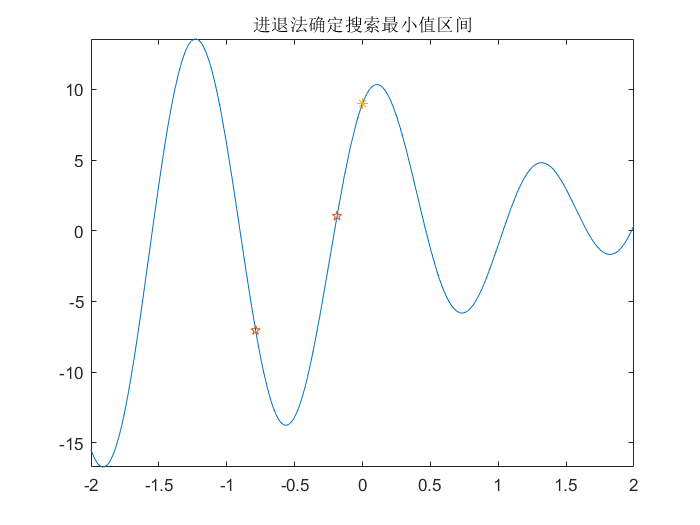

clear; clc;
fun = @(x) x + 6 * sin(4 * x) + 9 * cos(5 * x);
[lb, ub] = OptAdvanceRetreat(fun, 0, 0.0125);
fplot(fun, [-2, 2])
hold on 
plot([lb, ub], fun([lb, ub]), 'p');
plot(0, fun(0), '*');
hold off
title('进退法确定搜索最小值区间');

function [lb, ub] = OptAdvanceRetreat(fun, x0, h0)
%{
函数功能：进退法确定搜索最小值区间
输入：
  fun：目标函数句柄；
  x0：初始点；
  h0：初始步长，默认值为 0.0125；
输出：
  lb：搜索区间左端点；
  rb：搜索区间右端点；
%}
if nargin < 3
   h0 = 0.0125;
end
if nargin < 2
   error('输入参数不足！');
end
% 初始情况
k = 0;
x = x0;
h = h0;
while 1
    x2 = x + h;           % 新的区间端点
    k = k + 1;
    f2 = fun(x2);
    f = fun(x);
    if f2 < f             % x1右侧有下降趋势，向右搜索
        x1 = x;
        x = x2;
        h = 2 * h;
    else
        if k == 1         % x1右侧有上升趋势，反向搜索
            h = -h;       % 反向搜索 
            x1 = x2;
        else
            % 输出，确定区间为 x1 和 x2 之间
            lb = min(x1, x2);
            ub = max(x1, x2);
            break;  
        end
    end
end
end